summary(carpricesedited)

Variables:

    year: 2013×1 double

        Values:

            Min             2011  
            Median          2012  
            Max             2015  
            NumMissing      1     

    make: 2013×1 categorical

        Values:

            Acura               33   
            Audi                34   
            BMW                312   
            Buick                7   
            Cadillac            13   
            Chevrolet           95   
            Chrysler             9   
            Dodge               16   
            FIAT                 2   
            Ferrari              1   
            Ford               135   
            GMC                  3   
            Honda               96   
            Hyundai            190   
            Infiniti           253   
            Jaguar              16   
            Jeep                17   
            Kia                 91   
            Land Rover          10   
  

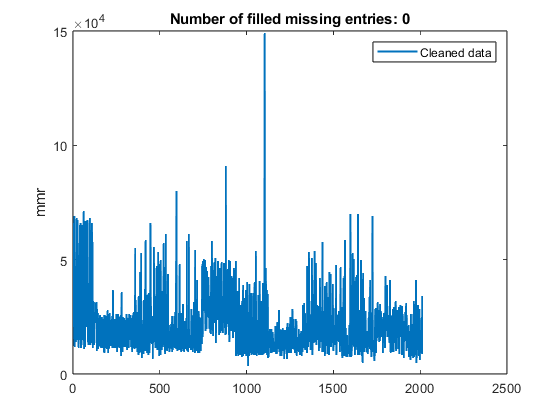

% Fill missing data
[newTable,missingIndices2] = fillmissing(carpricesedited,"previous");

% Display results
clf
plot(newTable.mmr,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices2(:,12)),newTable.mmr(missingIndices2(:,12)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,...
    "DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices2(:,12)))

hold off
legend
ylabel("mmr")

clear missingIndices2

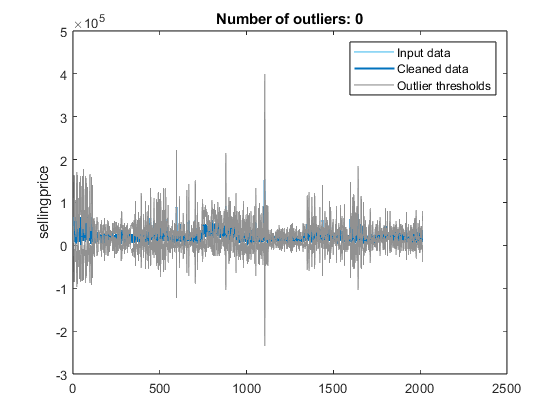

% Remove outliers
[newTable2,outlierIndices] = rmoutliers(newTable,"movmedian",2,...
    "DataVariables",["year","condition","odometer","mmr","sellingprice"]);

% Display results
clf
plot(newTable.sellingprice,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),newTable2.sellingprice,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Additional outlier computations for plot
[outliersForPlot,thresholdLow,thresholdHigh] = isoutlier(newTable.sellingprice,...
    "movmedian",2);

% Plot outliers
plot(find(outliersForPlot),newTable.sellingprice(outliersForPlot),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outliersForPlot))

% Plot outlier thresholds
plot([(1:numel(newTable.sellingprice))'; missing; (1:numel(newTable.sellingprice))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],"Color",[145 145 145]/255,...
    "DisplayName","Outlier thresholds")

hold off
legend
ylabel("sellingprice")

clear outliersForPlot thresholdLow thresholdHigh

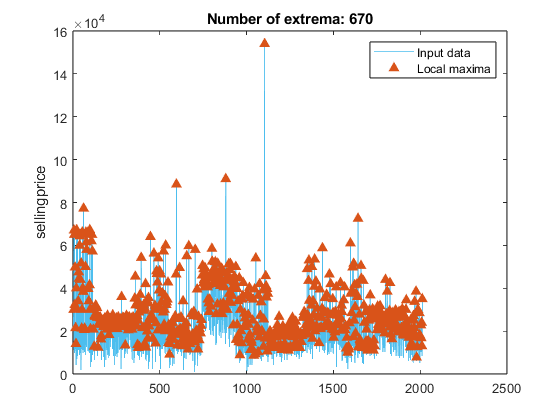

% Find local maxima
maxIndices = islocalmax(newTable2,...
    "DataVariables",["year","condition","odometer","mmr","sellingprice"]);

% Display results
clf
plot(newTable2.sellingprice,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices(:,13)),newTable2.sellingprice(maxIndices(:,13)),"^",...
    "Color",[217 83 25]/255,"MarkerFaceColor",[217 83 25]/255,...
    "DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices(:,13)))
hold off
legend
ylabel("sellingprice")

idx = 0.2

idx = 0.2000

hpartition = cvpartition(length(newTable2.sellingprice),'HoldOut',idx)

hpartition = Hold-out cross validation partition
   NumObservations: 2013
       NumTestSets: 1
         TrainSize: 1611
          TestSize: 402

idxTrain = training(hpartition);
trainData = newTable2(idxTrain,:)

trainData = 1611×13 table
    year      make              model                     trim                  body        transmission    condition    odometer    color     interior                          seller                           mmr     sellingprice
    ____    _________    ___________________    _________________________    ___________    ____________    _________    ________    ______    ________    __________________________________________________    _____    ____________

    2015    Kia          Sorento                LX                   

idxTest= test(hpartition);
testData=newTable2(idxTest,:)

testData = 402×13 table
    year      make        model            trim             body        transmission    condition    odometer    color     interior                          seller                           mmr     sellingprice
    ____    _________    ________    ________________    ___________    ____________    _________    ________    ______    ________    __________________________________________________    _____    ____________

     NaN    make         model       trim                body           transmission       NaN          NaN    

testAnswers = testData.sellingprice;
testData = removevars(testData,"sellingprice")

testData = 402×12 table
    year      make        model            trim             body        transmission    condition    odometer    color     interior                          seller                           mmr 
    ____    _________    ________    ________________    ___________    ____________    _________    ________    ______    ________    __________________________________________________    _____

     NaN    make         model       trim                body           transmission       NaN          NaN      color     interior    seller                                    

trainedModel

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'body'  'color'  'condition'  'interior'  'make'  'mmr'  'model'  'odometer'  'seller'  'transmission'  'trim'  'year'}
        RegressionSVM: [1×1 RegressionSVM]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


MyModel = trainedModel.RegressionSVM

MyModel =   RegressionSVM
           PredictorNames: {'year'  'make'  'model'  'trim'  'body'  'transmission'  'condition'  'odometer'  'color'  'interior'  'seller'  'mmr'}
             ResponseName: 'Y'
    CategoricalPredictors: [2 3 4 5 6 9 10 11]
        ResponseTransform: 'none'
                    Alpha: [763×1 double]
                     Bias: 2.0283e+04
         KernelParameters: [1×1 struct]
                       Mu: [1×765 double]
                    Sigma: [1×765 double]
          NumObservations: 1611
           BoxConstraints: [1611×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [1611×1 logical]
                   Solver: 'SMO'


  Properties, Methods


predictedsellingprice= trainedModel.predictFcn(testData)

predictedsellingprice = 	1.0e+04 *

       NaN
    2.0319
    1.6054
       NaN
    1.9596
    6.3189
    2.9710
    1.9985
    1.1499
    1.2093


table(predictedsellingprice)

ans = 402×1 table
    predictedsellingprice
    _____________________

              NaN        
            20319        
            16054        
              NaN        
            19596        
            63189        
            29710        
            19985        
            11499        
            12093        
            41253        
            21088        
              NaN        
            18868        
            64145        
            12938        


testErrors= testAnswers - predictedsellingprice

testErrors = 	1.0e+04 *

       NaN
    0.1181
    0.0946
       NaN
   -0.0096
    0.1061
   -0.2210
    0.0765
    0.0001
   -0.2293


%testAvgError=sum(abs(testErrors)) ./length(testAnswers)
testLoss= loss(MyModel,testData,testAnswers)

testLoss = 3.3552e+06

trainLoss = loss(MyModel,trainData,trainData.sellingprice)

trainLoss = 4.1724e+06

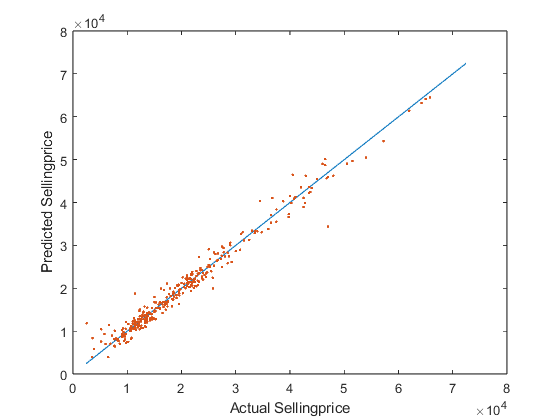

plot(testAnswers, testAnswers);
hold on
plot(testAnswers,predictedsellingprice,".");
hold off
xlabel('Actual Sellingprice');
ylabel('Predicted Sellingprice');

trainAbove50000= numel(trainData.sellingprice(trainData.sellingprice>50000))

trainAbove50000 = 37

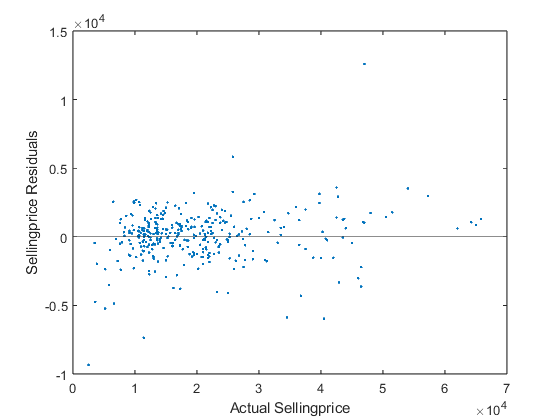

plot(testAnswers,testErrors,".")
hold on
yline(0)
hold off
xlabel('Actual Sellingprice')
ylabel('Sellingprice Residuals')

testData(testErrors>5000 | testErrors<-5000,:)

ans = 7×12 table
    year       make             model             trim         body       transmission    condition    odometer    color    interior                          seller                           mmr 
    ____    __________    _________________    __________    _________    ____________    _________    ________    _____    ________    __________________________________________________    _____

    2013    Hyundai       Santa Fe             Sport 2.0T    SUV           automatic          5         10747      black     black      hyundai motor america/co car                  

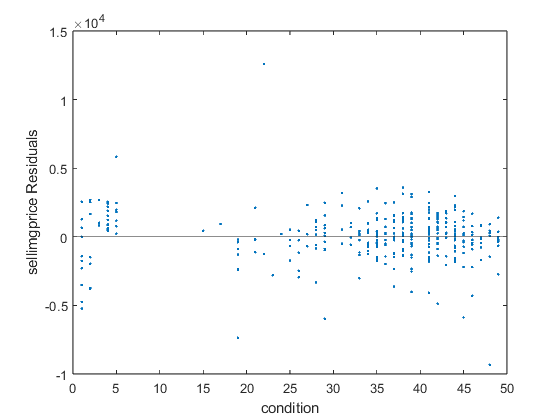

plot(testData.condition, testErrors, ".");
hold on 
yline(0)
hold off
xlabel('condition')
ylabel('sellimgprice Residuals')

model_sellingprice= trainedModel;
save model_sellingprice.mat;